# First Law of Thermodynamics 

[⇦ Overview](matlab: OpenOverview)

Thermodynamics is the study of energy in motion. How can we describe the process of boiling a tea kettle on the stove? Why does an engine generate useful work? What does insulation do? How does a generator work? What about a battery? Or a refrigerator? Why are the equations that describe LR circuits the same equations that describe spring-mass systems? All of these questions are part of the study of thermodynamics. The fundamental ideas of thermodynamics are formulated as a series of laws. The first law of thermodynamics is the conservation of energy.

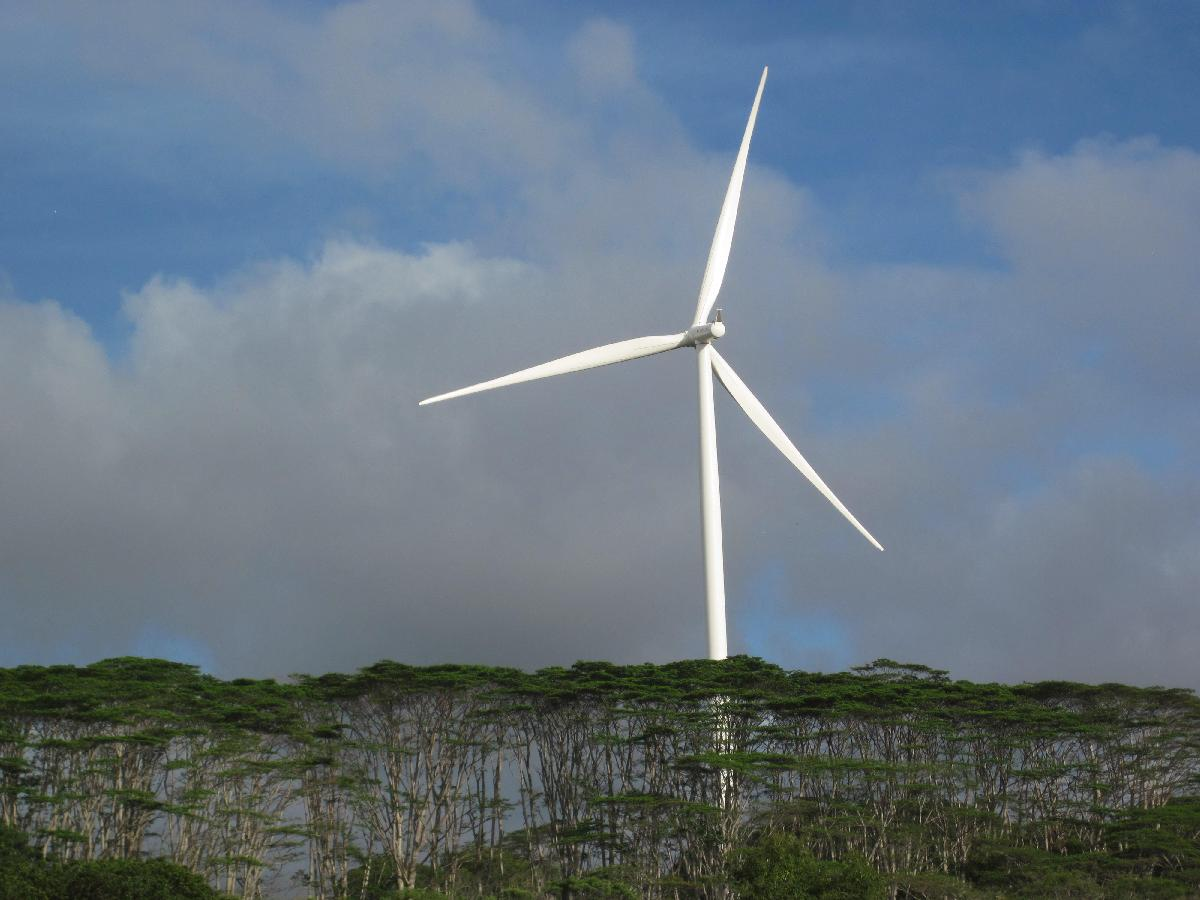

A wind turbine in Oahu used by the USGS for [research](https://www.usgs.gov/media/images/wind-turbine-towering-over-trees)

Applying the first law of thermodynamics to determine ways to generate useful energy has interested humans for many years. Energy cannot be created or destroyed, but it can change form. A wind turbine, for instance, converts kinetic energy from the air into rotational energy and then into electrical energy.

## **Before you get started**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB Toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon  at the top right of the Live Editor pane.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if the sections are run out of order.

## What is energy?

Energy is a measure of the ability to perform work. Kinetic energy is active and related to motion, such as heat or velocity. Potential energy is latent and related to stored energy, such as batteries or elevation in a gravitational field. All energy can be measured in terms of units.

## Units

### Fundamental Units

Fundamental units measure aspects of the physical world that are classically accepted as both measurable and incomparable. In the SI (metric) system, the fundamental units are:

- length (meter, m)

- mass (kilogram, kg)

- time (second, s)

- temperature (kelvin, K)

- electric current (ampere, A)

- light (candela, cd)

- matter (mole, mol)

### Derived Units

All secondary units can be expressed as combinations of fundamental units. Here is a selection of derived units:

- volume (cubic meters, m$^3$)

- velocity (meters per second, m/s)

- force (newton, N = kg$\cdot$m/s$^2$)

- work (joule, J = N$\cdot$m = kg$\cdot$m$^2$/s$^2$)

- power (watt, W = J/s = kg$\cdot$m$^2$/s$^3$)

### Forms of energy

Energy can come in many forms, several of which align with traditional engineering disciplines: mechanical, electrical, chemical, thermal, gravitational, atomic, etc. It is likely that you can come up with different ways of describing energy based on some of the formulas for computing different forms of energy that you have encountered over the years:


$$E = mc^2$$
             
$$K = \frac{1}{2}mv^2$$
            
$$P = mhg$$


#### ** Exercise 1. **

In this exercise, you should use combinations of the fundamental units: `length, mass, time, temperature, electric_current, light,` and `matter`. You can combine them with arithmetic operators, including `*, /, `and` ^.`

a) What are the fundamental units of $E$?

u = symunit;
length = u.m;  
mass = u.kg;
time = u.s;
temperature = u.K;
electric_current = u.A;
light = u.cd;
matter = u.mol;
try
checkEnergyUnits( 0,"E");
catch
    disp("Please use the fundamental units:" ...
        + newline + "length, mass, time, temperature, electric_current, light, matter")
end
clear u length mass time temperature electric_current light matter
 

b) What are the fundamental units of $K$?

u = symunit;
length = u.m;
mass = u.kg;
time = u.s;
temperature = u.K;
electric_current = u.A;
light = u.cd;
matter = u.mol;
try
checkEnergyUnits(0,"K");
catch
    disp("Please use the fundamental units:" ...
        + newline + "length, mass, time, temperature, electric_current, light, matter")
end
clear u length mass time temperature electric_current light matter
 

c) What are the fundamental units of $P$?

u = symunit;
length = u.m;
mass = u.kg;
time = u.s;
temperature = u.K;
electric_current = u.A;
light = u.cd;
matter = u.mol;
try
checkEnergyUnits(0,"P");
catch
    disp("Please use the fundamental units:" ...
        + newline + "length, mass, time, temperature, electric_current, light, matter")
end
clear u length mass time temperature electric_current light matter
 

The SI unit of energy is the joule (J). One joule is the amount of energy required to apply one Newton of force across one meter of distance. In other words, 


$$1 \text{ J} = 1 \frac{\text{kg} \cdot \text{m}^2}{\text{s}^2}$$


This might sound familiar. Another form of energy is work:


$$\text{Work} = \text{Force} \cdot \text{Distance}$$


such as when Newton's law gives the force, $\text{F} = \text{ma}$, 


$$\text{Work} = \left(\text{Mass}\cdot\text{Acceleration}\right) \cdot \text{Distance}$$



$$= \left(\text{kg} \cdot \frac{\text{m}}{\text{s}^2}\right) \cdot \text{m}$$
                   

#### ** Exercise 2.**

Which of the following is a joule of electrical energy? 

exercise2(false,false,false)
 

## What is a conservation law?

A conservation law states that the change in some specified quantity is zero. Such a quantity is called *conserved*. In particular, this means that conserved quantities cannot be created or destroyed (although they can be moved around or transformed from one form to another).

### Conservation of mass

One classical conservation law is the conservation of mass. The conservation of mass is a common law that is played with by magicians. Everyone knows that if you have a rabbit in a hat and no rabbits enter or leave the hat, there must still be a rabbit in the hat. 

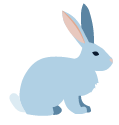

When a magician shows you that the rabbit has disappeared, you are surprised because it violates a fundamental law of thermodynamics. This is where the most incredible stage magic comes in: convincing the audience that fundamental laws about how the world works are being violated while not actually violating any such laws. 

#### ** Exercise 3.**

 A stage magician shows an empty hat, puts in a rabbit, then shows that the hat is empty again before pulling out three silk handkerchiefs. According to the law of the conservation of mass:

exercise3(0)

### What is a system?

Defining a *system* involves delineating the bounds of what is being described. This system might be defined as a quantity of matter or a specific region of space called a *control volume*. For the stage magician, some tricks are designed to convince the audience that the system is solely a top hat. In fact, the actual system includes the magician's body and clothing or perhaps other cleverly designed elements of the stage setting. To define a system, one needs to identify what is inside and outside the system, and where the boundary between the two is. A system may be *closed*, meaning nothing crosses the boundary, making it easy to analyze. In an *open* system, matter and energy can cross the boundary of the control volume and must be properly tracked for analysis. For both open and closed systems, the boundaries can be fixed, e.g., a sealed tank or a fixed volume in a pipe, or movable, e.g., the chamber of a piston or the volume of a jet engine in flight. 

#### ** Exercise 4.**

a) Consider the control volume inside a teapot recently filled with boiling water. 

 

teaplot = drawTeapot;

addSteam("?");

b) Consider the control volume inside a perfectly insulated thermos recently filled with boiling water.

 
drawThermos;

opt = "?";
checkThermos(opt)

In thermodynamics, as in stage magic, it is crucial to clearly identify the system that is being studied. A conservation law only applies to a properly identified system.

 **Reflect**.

- What scenarios can you imagine that can be described as a closed system?

- What scenarios can you imagine that can be described as an open system?

- What happens to energy in a closed system? What happens to energy in an open system? 

### Conservation of energy

The first law of thermodynamics is the conservation of energy. It says that for any system undergoing any process, 

$\displaystyle 
E_{\text{in}}-E_{\text{out}} = \Delta E_{\text{system}}$.

This can be harder to track because we don't have as much intuition about energy as we do about mass, so equations can help us understand where the energy is in our system. In a mechanical system, for instance, the total energy in a closed system can be written as:


$$K_{\text{initial}} + P_{\text{initial}} = K_{\text{final}} + P_{\text{final}} + \text{W}$$


where $K$ is the kinetic energy, $W$ is the work, and $P$ is the potential energy. The total energy in a closed system cannot change because $E_{\text{in}}$ and $E_{\text{out}}$ must be zero. This does not mean that nothing can change! Because there are many different forms that energy can take we could study systems where chemical potential energy is converted to heat and light:

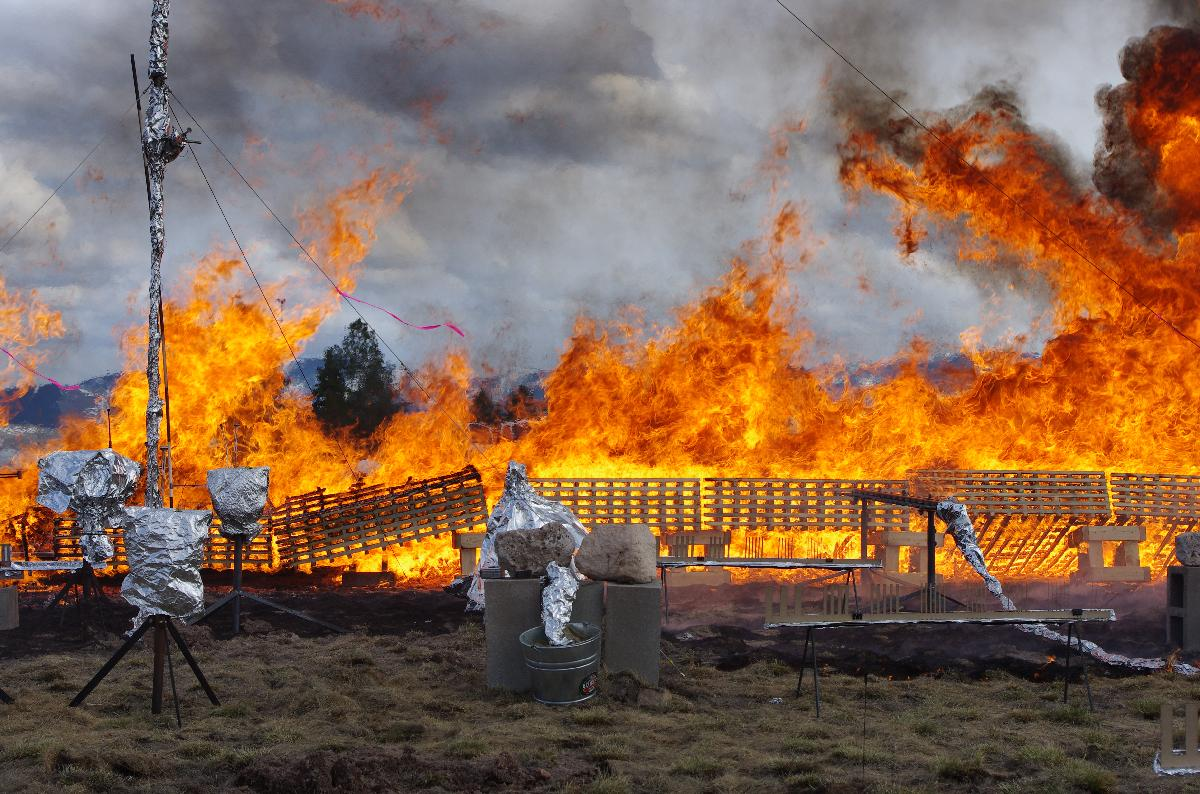

A controlled burn photographed by [Rachel A Loehman](https://www.usgs.gov/media/images/controlled-fire-studies-provide-data-archaeological-sites-impacts) of the USGS.

Or where mechanical rotational energy is converted to electrical energy:

A wind turbine in Oahu being used by the USGS for [research](https://www.usgs.gov/media/images/wind-turbine-towering-over-trees)

or many others. 

#### ** Exercise 5.**

Let's assume that the Great Pyramid of Giza was built using only human power. 

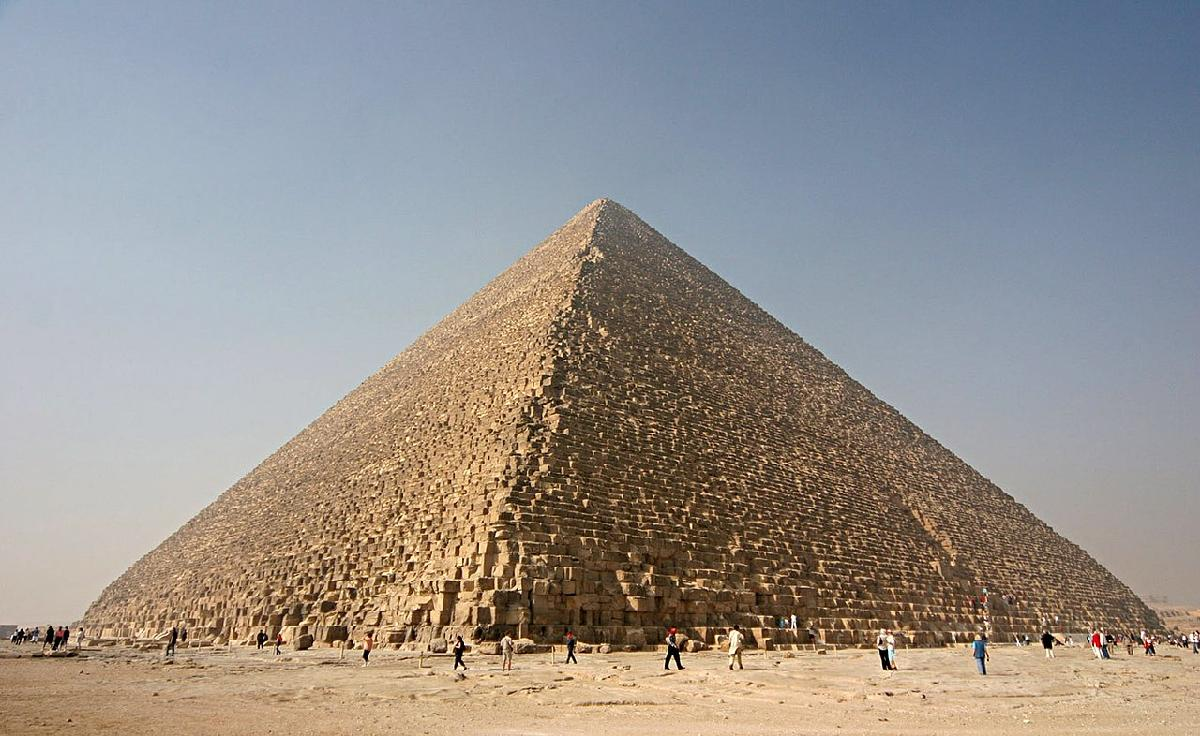

Photo credit: Nina Aldin Thune, [Wikimedia Commons](https://commons.wikimedia.org/wiki/File:Kheops-Pyramid.jpg), licensed: [CC BY-SA 3.0](https://creativecommons.org/licenses/by-sa/3.0/deed.en)

Assume that the pyramid is a solid square-based right pyramid 138.5 m tall with a base that is 230 m on a side made of solid limestone. Estimate how many human-days were required to build it.

myGuess = 10;

Then apply the first law of thermodynamics to the problem. A kilocalorie (also called a Calorie, nutritional calorie, or popularly just 'calorie') is the energy required to raise the temperature of one kilogram of water one degree Celsius. One standard abbreviation for a kilocalorie is C. Without starving the workforce, how much extra energy can they supply?

baseEnergyRequirement = 2000; % in C
foodConsumed = 2000;  % in C
 
netEnergyAvailable = (foodConsumed-baseEnergyRequirement)*4.1868*0.2;  % kJ per person per day
displayFormula(["'The net energy available, assuming 20% efficiency, is estimated at '",string(netEnergyAvailable),"' kJ per person per day.'"])
displayFormula("'You can refer to this value using the variable:'")
disp("netEnergyAvailable")

Now we need to calculate how much mass must be lifted (we will neglect the mass of the people themselves with the idea that it is included in their basic energy requirements). Look up the density of limestone and enter the value here:

rho =  0;  % in kg/m^3
 
massDensityFlag = checkMassDensity(rho,netEnergyAvailable);

Compute the work:

 
if ~exist("hintCount","var")
    hintCount = 1;
else
    hintCount = hintCount + 1;
end
offerHint(hintCount)
if hintCount == 6
    disp("This is the last hint. If you want to see the same hints cycle you can continue to ask for them.")
    clear hintCount
end

syms y
myPeopleDays = double(vpa( 0));
checkMyWork(myPeopleDays,rho,230,138.5,netEnergyAvailable)

Assuming 20 years to build the pyramid, how many people are required if they work 300 days per year? 

numPeople =  0;
sanityCheckPeople(numPeople,myGuess,myPeopleDays,"year")

How many people are required if they work only 65 days per year?

numMorePeople =  0;
sanityCheckPeople(numMorePeople,myGuess,myPeopleDays,"season")

**Reflect**.

- Did we use appropriate units in Exercise 5? Or would different units have made your calculations easier? Or is your answer easier to understand?

[⇦ Return to the navigation page](matlab: OpenOverview)

## Helper Functions

If you want to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

function sanityCheckPeople(num,orig,pdays,opt)
arguments
    num (1,1) {mustBeNonnegative}
    orig (1,1) 
    pdays (1,1) {mustBeNonnegative}
    opt (1,1) {mustBeMember(opt,["year","season"])}
end

if round(num,0)==num
    switch opt
        case "year"
            myFactor = 20*300;
        case "season"
            myFactor = 20*65;
    end
    if num == ceil(pdays/myFactor)
        displayFormula(["'You estimated that approximately '", string(num), "' individuals are needed each '", opt, "'.'"])
        displayFormula("'That makes sense with the assumptions you have made.'")
        displayFormula(["'You had originally claimed that '", string(orig), "' people were needed.'"])
        displayFormula(["'Were you thinking about total individuals or people by '", opt, "'?'"])
    elseif num == round(pdays/myFactor,0)
        displayFormula(["'You rounded down to '", string(num), "' people each '",opt,"'. Does that make sense?'"])
        displayFormula(["'You estimated that approximately '", string(num), "' individuals are needed each '", opt, "'.'"])
        displayFormula(["'You had originally claimed that '", string(orig), "' people were needed.'"])
        displayFormula(["'Were you thinking about total individuals or people by '", opt, "'?'"])
    elseif abs(num-ceil(pdays/myFactor)) < 4
        displayFormula(["'You estimated that approximately '", string(num), "' individuals are needed each '", opt, "'.'"])
        displayFormula("'This value is close to a reasonable value, but you may have rounded too early.'")
        displayFormula("'Try to be as exact as possible, while still keeping your scenario in mind.'")
    else
        displayFormula(["'Your result of '", string(num), "' does not align with your estimate of '", string(pdays), "' people-days.'"])
    end
else
    fracPerson = num-floor(num);
    displayFormula(["'You are estimating that '", string(num), "' people are needed.'"])
    displayFormula(["'What is a '", string(fracPerson), "' of a person? Please enter a whole number of people.'"])
end
end

function checkMyWork(myDays,rho,width,height,ener)
displayFormula(["'You entered a total of approximately '", string(round(vpa(myDays),2)), "' people-days.'"])
[peopleDays,msG,msY,msRho,workNeeded] = howMuchWork(rho,width,height,ener);
if myDays == 0
    displayFormula("'This is the default value. Please calculate your solution.'")
elseif abs(abs(myDays-peopleDays)/peopleDays) < 0.01
    myDays = round(vpa(myDays),2);
    displayFormula(["'Excellent. Your solution of '", string(myDays), "' people-days is a good enough estimate.'"])
    displayFormula("'You can use the variable'")
    disp("myPeopleDays")
    displayFormula("'to refer to this value.'")
elseif abs(abs(myDays-peopleDays)/peopleDays) < 0.1
    displayFormula("'You may have rounded more than intended. Your answer is close, but can be better.'")
elseif abs(abs(myDays-msG)/msG) < 0.01
    displayFormula("'You appear to have forgotten to use the weight density rather than the mass density.'")
elseif abs(abs(myDays-msY)/msY) < 0.01
    displayFormula("'You appear to have forgotten to multiply the force by the distance traveled. Check your units.'")
elseif abs(abs(myDays-msRho)/msRho) < 0.01
    displayFormula("'You appear to have forgotten to use a mass-density at all. Check your units.'")
elseif abs(abs(myDays-workNeeded)/workNeeded) < 0.01
    displayFormula("'You appear to have calculated the work required rather than the people-days.'")
else
    displayFormula("'Your answer does not match the expected value. Please review the hints and try again.'")
end
end

function offerHint(hintCount)
switch hintCount
    case 1
        displayFormula("'Work = (Force) * (Distance)'")
    case 2
        syms rho
        displayFormula("'Force = (Mass Density) * (Gravitational Acceleration) * (Volume)'")
        weightDensity = rho*vpa(9.81);
        displayFormula(["'Force = '" ,string(weightDensity), "'*(Volume)'"])
        displayFormula(["'where rho = '", string(rho), "' kg/m^3 is the mass density and g = 9.81 m/s^2 is the acceleration due to gravity'"])
    case 3
        displayFormula("'You need to determine the cross-sectional area of the pyramid as a function of height.'")
    case 4
        syms b x y h
        displayFormula(["'Let '",string(b),"'= base and '",string(h),"'= height while x is the " + ...
                      "horizontal distance and y is the vertical distance.'"])
        rat1 = b/h;
        rat2 = x/(h-y);
        displayFormula(["'The slope of the pyramid is: '", string(rat1),"' = '",string(rat2)])
    case 5
        syms b y h
        displayFormula(["'Let '",string(b),"'= base and '",string(h),"'= height while y is the vertical distance.'"])
        myArea = ((h-y)*b/h)^2;
        displayFormula(["'The cross-sectional area of a square pyramid at height y is '", string(myArea), "' if the base of the pyramid is y=0.'"])

    case 6
        syms a b Force(x)
        displayFormula("Work = int(@(x)x*Force(x),a,b)")
        displayFormula("'where x=a and x=b are the starting and finishing positions'")
        displayFormula("'and Force(x) is the force as a function of x.'")
    otherwise
        displayFormula("'No more hints are available. If you want to see them again, run'")
        disp("clear hintCount")
        displayFormula("'in the Command Window'")
end
if hintCount < 6
    disp("Do you need another hint?")
end
end

function [workNeeded,missingG,missingY,missingRho] = pyramidWork(rho,width,height)
g = 9.81;
workNeeded = integral(@(y) g*rho*y.*(width-width/height*y).^2,0,height)/1000;  % in kJ
missingG = integral(@(y) rho*y.*(width-width/height*y).^2,0,height)/1000;  % in kJ
missingY = integral(@(y) g*rho*(width-width/height*y).^2,0,height)/1000;  % in kJ
missingRho = integral(@(y) g*y.*(width-width/height*y).^2,0,height)/1000;  % in kJ
end

function [peopleDays,msG,msY,msRho,workNeeded] = howMuchWork(rho,width,height,ener)
[workNeeded,missingG,missingY,missingRho] = pyramidWork(rho,width,height);  % in kJ
peopleDays = workNeeded/ener;
msG = missingG/ener;
msY = missingY/ener;
msRho = missingRho/ener;
end


function massFlag = checkMassDensity(rho,flag)
if flag > 0
    massFlag = 0;
    if rho > 2700
        displayFormula("'This is too high for the mass density of limestone in kilograms per cubic meter.'")
    elseif rho >= 1500
        displayFormula("'This is a reasonable estimate for the mass density of limestone.'")
        displayFormula("'You can refer to this mass density using the variable:'")
        disp("rho")
        massFlag = 1;
    elseif (rho >= 1.5 && rho <= 2.7) || (rho > 93 && rho < 170)
        % This is the numerical range for mass density in g/cm^3 and lb/ft^3
        displayFormula("'This is too low to be the mass density of limestone in kilograms per cubic meter.'")
        displayFormula("'Is your mass density in the correct units?'")
    elseif rho > 2.7 || (rho > 0 && rho < 1.5)
        displayFormula("'This is too low an estimate for the mass density of limestone.'")
    elseif rho == 0
        displayFormula("'You must set a reasonable value to continue.'")
    else
        displayFormula("'This is not a reasonable mass density.'")
    end
    if massFlag == 0
        displayFormula("'Please try again.'")
    else
        displayFormula("'Please continue with the problem.'")
    end
else
    disp("There must be some net energy available to attempt to build a pyramid," ...
        + newline + "please increase the amount of food for the workers.")
    massFlag = -1;
end
end

function checkEnergyUnits(opt,arg)
u = symunit;
if opt == 0
    disp("Zero is not a fundamental unit. Please use the fundamental units:" ...
        + newline + "length, mass, time, temperature, electric_current, light, matter")
elseif checkUnits(simplify(opt) == u.kg*u.m^2/u.s^2,"Consistent")
    disp("That is correct. The fundamental units of " + arg + " are mass*length^2/time^2. In SI this is:")
    displayFormula("u.kg*u.m^2/u.s^2")
else
    disp("You are claiming: ")
    displayFormula("opt")
    disp("That is incorrect units for " + arg + ". Please try again.")
end
end

function exercise2(tf1,tf2,tf3)
u = symunit;
if all([tf1,tf2,tf3])
    disp("That is correct. These are all ways to express one joule!")
    ohmSI = unitConvert(u.ohm,"SI");
    wattSI = unitConvert(u.watt,"SI");
    voltSI = unitConvert(u.volt,"SI");
    displayFormula("u.ohm == ohmSI")
    displayFormula("u.watt == wattSI")
    displayFormula("u.volt == voltSI")
elseif any([tf1,tf2,tf3])
    disp("That is true but not complete; there are still more ways "...
        + newline + "to express one joule here.")
else
    disp("What at the SI units of an ohm? Or a watt? Or a volt?")
end
end

function exercise3(opt)
if opt == 0
    disp("That is the default. You know more about the top hat than that.")
elseif opt == 1
    disp("That is correct. The rabbit must still exist. Even though we cannot"...
        + newline + "see it, it must still be present. It may not be present inside the hat," ...
        + newline + "however. Stage magicians excel at convincing their audience to focus on some" ... 
        + newline + "parts of the stage and fail to notice others.")
elseif opt == 2
    disp("This may well be true, but if it is true, where is the rabbit?" ...
        + newline + "The conservation of mass says that the rabbit did not disappear." ...
        + newline + "Do you believe the rabbit was transformed into three silk scarves?" ...
        + newline + "That does not seem to be enough mass. The rest would have to go somewhere.")
elseif opt == 3
    disp("The handkerchiefs may have been in the hat at the beginning of the" ...
        + newline + "trick, but they are no longer in the hat. What was put in?" ...
        + newline + "Negative mass is, so far at least, an interesting thought experiment in theoretical" ...
        + newline + "physics. We cannot use negative silk scarves.")
else
    disp("How did you get here? This wasn't an option.")
end
end

function ax = drawTeapot
figure
[verts, faces, cindex] = teapotGeometry;
cmap = colormap(jet);           % change the colormap
patch([-3 3.4326 3.4326 -3 -3],[-2 -2 2 2 -2],cmap(1,:),"FaceAlpha",0.3)
patch([3.7 3.7 3.7 3.7 3.7],[-2.2 -2.2 2.2 2.2 -2.2],[0 3.5 3.5 0 0],cmap(155,:))
patch([-3 -3 3.7 3.7 -3],[-2.2 -2.2 -2.2 -2.2 -2.2],[0 3.5 3.5 0 0],cmap(155,:))
tp = patch('Faces',faces,'Vertices',verts,'FaceVertexCData',cindex,'FaceColor','interp');
ax = gca;
view(-151,30)     % change the orientation
axis equal off    % make the axes equal and invisible
tp.FaceAlpha = 1;           % remove the transparency
tp.LineStyle = 'none';      % remove the lines
colormap(bone)           % change the colormap
end

function addSteam(opt)
arguments
    opt (1,1) string {mustBeMember(opt,["?" "open" "closed"])}
end

if opt == "?"
else
    if opt == "closed"
        disp("No, mass and energy can move in and out of this system. Do you see it?")
        ax = drawTeapot;
        zVals = 2:0.01:3.4;
        hold on
        scaleFactor = 0.5;
        myJitter = .1*sin(2*pi/scaleFactor*zVals);
        plot3(ax, 3.7*ones(size(zVals)),-1*ones(size(zVals))+myJitter,zVals,"LineWidth",3,"Color","w")
        plot3(ax, 3.7*ones(size(zVals)),-1.3*ones(size(zVals))+myJitter,zVals-.2,"LineWidth",3,"Color","w")
        plot3(ax, 3.7*ones(size(zVals)),-.7*ones(size(zVals))+myJitter,zVals*.85+.45 ...
            ,"LineWidth",3,"Color","w")
        hold off
    elseif opt == "open"
        disp("That is correct, mass and energy can move in and out of this system."+newline+newline)
        disp("Note: This is why tea cozies exist.")
        teacozy = imread("Images/Tea_cosy.jpg");
        imshow(teacozy)
        disp("Image credit: erinmahollitz (user name on Flickr), CC BY 2.0 <https://creativecommons.org/licenses/by/2.0>, via Wikimedia Commons")
    else
        disp("How did you get here?")
    end
end
end

function drawThermos
figure
tVals = linspace(0,2*pi,100);
xCoords = cos(tVals);
yCoords = sin(tVals);
myHeight = 5;
myVertices = [xCoords' yCoords' zeros(100,1); xCoords' yCoords' myHeight*ones(100,1)];
myFaces = [(1:100)' ([(2:100) 1])' 100+([(2:100) 1])' 100+(1:100)'];
halfCIndex = hsv(100);
cIndex = [halfCIndex; flipud(halfCIndex)];
floorFaces = [(1:49)' (2:50)' (99:-1:51)' (100:-1:52)'];
roofFaces = floorFaces + 100;
p = patch('Faces',[myFaces;floorFaces;roofFaces],'Vertices',myVertices,'FaceVertexCData',cIndex,'FaceColor','interp');

view(-151,30)     % change the orientation
axis equal off    % make the axes equal and invisible
p.LineStyle = 'none';      % remove the lines
ax = p.Parent;
hold on
plot3(ax,xCoords(7:56),yCoords(7:56),myHeight*.82*ones(50,1),"g-","LineWidth",3)
plot3(ax,xCoords(7:56),yCoords(7:56),myHeight*.8*ones(50,1),"k-","LineWidth",3)
hold off
end

function checkThermos(opt)
if opt == "?"
    disp("Please select 'open' or 'closed'.")
elseif opt == "closed"
    disp("That is correct, a sealed volume inside a perfect insulator is a closed system.")
elseif opt == "open"
    disp("While a practical answer in the world, note that this thermos is described as a perfect insulator." ...
        + newline + "This means the heat flow across the boundary must be 0. To be a useful thermos, it should not" ...
        + newline + "leak, so there is no mass flow across the boundary. What type of system is that?")
else
    disp("How did you get here?")
end
end

%#ok<*NASGU>